% AOCS hybrid model sequential delta slew
%
% Reaction wheel + RCS desaturation model.
%
% Spacecraft executes:
%   1) delta(theta_e1)
%
% Only angle changes produce spacecraft slews.
% theta_e1 is treated as thrust-vector steering about the spacecraft Z axis.
%
% Reaction wheel logic:
%   - Each commanded slew is executed at a specified slew rate.
%   - Wheel momentum contribution is H = I*omega.
%   - All theta_e1 slews add positive-Z momentum.
%   - When |H_RW| reaches 50 Nms, RCS desaturates wheels back to 5 Nms.

clear;
clc;
close all;

%% Section 1: Load data

data = load('theta_e1_and_theta_e2.mat');

R_SC = data.R_SC;
theta_SP = data.theta_SP;
thrust_vector = data.thrust_vector;

theta_e1 = data.theta_e1;
theta_e2 = data.theta_e2;

N = size(R_SC,1);

%% Section 2: Define mission and hardware parameters

mission_years = 16.79;
T_total = mission_years * 365.25 * 24 * 3600;
delta_t = T_total / (N-1);

% Spacecraft inertia tensor [kg*m^2].
I_body = [ ...
    16912.28,     0.00,     2.42 ;
        0.00,  2610.23,     0.68 ;
        2.42,     0.68, 14892.69 ];

% Reaction wheel saturation limit [N*m*s].
RW_H_sat = 50;

% Residual wheel momentum after desaturation [N*m*s].
RW_H_target = 5;

% Propulsion parameters.
Isp = 220;
g0 = 9.80665;

% Slew deadband threshold [rad].
theta_deadband = deg2rad(0.001);

% Assumed slew rate for executing theta_e1 maneuvers.
slew_rate_deg_s = 0.1;
slew_rate = deg2rad(slew_rate_deg_s);

%% Section 3: Build validity mask

valid_k = true(N,1);

for k = 1:N
    if any(isnan(R_SC(k,:,:)),'all')
        valid_k(k) = false;
    end
end

n_invalid = sum(~valid_k);

fprintf('Detected %d invalid timesteps\n', n_invalid);

Detected 169 invalid timesteps


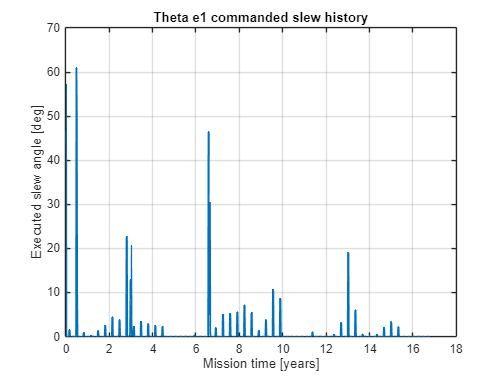


%% Section 4: Extract sequential delta angles

dtheta_e1 = zeros(N-1,1);
dtheta_e2 = zeros(N-1,1);
theta_total = zeros(N-1,1);

for k = 1:N-1
    if ~valid_k(k) || ~valid_k(k+1)
        continue;
    end

    % Compute incremental commanded rotations [rad].
    dtheta_e1(k) = theta_e1(k+1) - theta_e1(k);
    dtheta_e2(k) = theta_e2(k+1) - theta_e2(k);

    % Use only theta_e1 for this model.
    theta_total(k) = abs(dtheta_e1(k));
end

%% Section 5: Propagate reaction wheel momentum

H_RW = zeros(N,3);
H_RW_mag = zeros(N,1);
sat_flag = zeros(N,1);

desat_count = 0;
m_RCS_vec = [];
desat_times = [];

slew_time_s = zeros(N-1,1);
slew_H_mag = zeros(N-1,1);

% Store the pre-desaturation peak for plotting and table output.
wheel_H_peak_Nms = zeros(N-1,1);

for k = 1:N-1
    % Carry forward previous wheel momentum.
    H_RW(k+1,:) = H_RW(k,:);

    if ~valid_k(k) || ~valid_k(k+1)
        H_RW_mag(k+1) = norm(H_RW(k+1,:));
        continue;
    end

    if abs(dtheta_e1(k)) > theta_deadband
        % Treat theta_e1 as thrust-vector steering about body Z.
        axis1 = [0 0 1];

        % Compute time required to execute the slew at the assumed slew rate.
        slew_time_s(k) = abs(dtheta_e1(k)) / slew_rate;

        % Apply positive-Z steering momentum for all theta_e1 slews.
        omega1 = slew_rate .* axis1;

        % Compute wheel momentum contribution from this slew.
        H1 = (I_body * omega1')';

        % Save individual slew momentum magnitude.
        slew_H_mag(k) = norm(H1);

        % Accumulate positive-Z wheel momentum.
        H_RW(k+1,:) = H_RW(k+1,:) + H1;

        % Check saturation after this slew.
        H_norm = norm(H_RW(k+1,:));

        % Store the actual peak before any possible desaturation.
        wheel_H_peak_Nms(k) = H_norm;

        if H_norm >= RW_H_sat
            sat_flag(k+1) = 1;
            desat_count = desat_count + 1;

            % Store wheel momentum before desaturation.
            H_pre = H_RW(k+1,:);

            % Unload wheel momentum back to target magnitude.
            H_post = H_pre .* (RW_H_target / H_norm);

            % Compute angular momentum removed by RCS.
            DeltaH = H_pre - H_post;

            % Compute hydrazine required for desaturation.
            m_k = norm(DeltaH) / (Isp*g0);

            m_RCS_vec(end+1,1) = m_k;
            desat_times(end+1,1) = k+1;

            % Reset wheel state after desaturation.
            H_RW(k+1,:) = H_post;
        end
    end

    H_RW_mag(k+1) = norm(H_RW(k+1,:));
end

%% Section 6: Identify slew events

is_slew = theta_total > theta_deadband;

maneuver_events = struct( ...
    'step',{}, ...
    'theta_e1_deg',{}, ...
    'slew_time_s',{}, ...
    'slew_H_Nms',{}, ...
    'wheel_H_peak_Nms',{}, ...
    'wheel_H_after_Nms',{}, ...
    'had_desat',{}, ...
    'hydrazine',{});

event_count = 0;

for k = 1:N-1
    if is_slew(k)
        event_count = event_count + 1;

        ev = struct();
        ev.step = k;
        ev.theta_e1_deg = rad2deg(abs(dtheta_e1(k)));
        ev.slew_time_s = slew_time_s(k);
        ev.slew_H_Nms = slew_H_mag(k);
        ev.wheel_H_peak_Nms = wheel_H_peak_Nms(k);
        ev.wheel_H_after_Nms = H_RW_mag(k+1);
        ev.had_desat = sat_flag(k+1);

        if ~isempty(desat_times)
            mask = desat_times == (k+1);
            ev.hydrazine = sum(m_RCS_vec(mask));
        else
            ev.hydrazine = 0;
        end

        maneuver_events(event_count) = ev;
    end
end

%% Section 7: Build all slew events table

if event_count > 0
    Event_ID = (1:event_count)';
    Step = [maneuver_events.step]';
    Theta_e1_deg = [maneuver_events.theta_e1_deg]';
    Slew_Time_s = [maneuver_events.slew_time_s]';
    Slew_Time_min = Slew_Time_s ./ 60;
    Slew_H_Nms = [maneuver_events.slew_H_Nms]';
    Wheel_H_Peak_Nms = [maneuver_events.wheel_H_peak_Nms]';
    Wheel_H_After_Nms = [maneuver_events.wheel_H_after_Nms]';
    Desat_This_Step = logical([maneuver_events.had_desat])';
    Hydrazine_g = [maneuver_events.hydrazine]' .* 1000;
    Desat_Has_Occurred = false(event_count,1);

    for j = 1:event_count
        step_j = Step(j);
        Desat_Has_Occurred(j) = any(desat_times <= step_j + 1);
    end

    all_events_table = table( ...
        Event_ID, ...
        Step, ...
        Theta_e1_deg, ...
        Slew_Time_s, ...
        Slew_Time_min, ...
        Slew_H_Nms, ...
        Wheel_H_Peak_Nms, ...
        Wheel_H_After_Nms, ...
        Desat_This_Step, ...
        Desat_Has_Occurred, ...
        Hydrazine_g);
else
    all_events_table = table();
end

%% Section 8: Plot slew history

time_years = ((1:N-1) .* delta_t) ./ (365.25*24*3600);

figure;
plot(time_years, rad2deg(theta_total), 'LineWidth',1.5);
xlabel('Mission time [years]');
ylabel('Executed slew angle [deg]');
title('Theta e1 commanded slew history');
grid on;

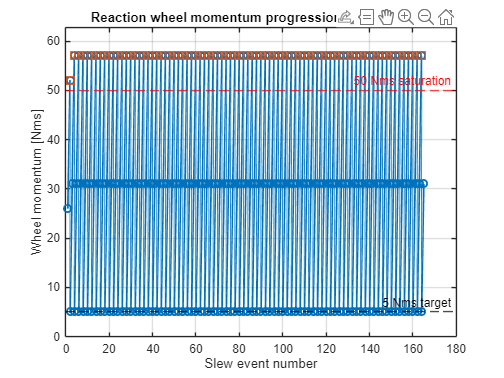


%% Section 9: Plot reaction wheel momentum progression

if event_count > 0
    x_plot = [];
    y_plot = [];
    desat_x = [];
    desat_y = [];

    for j = 1:event_count
        peak_j = maneuver_events(j).wheel_H_peak_Nms;
        after_j = maneuver_events(j).wheel_H_after_Nms;

        if maneuver_events(j).had_desat
            % Plot the peak first, then the post-desaturation value at the same event.
            x_plot(end+1,1) = j;
            y_plot(end+1,1) = peak_j;
            x_plot(end+1,1) = j;
            y_plot(end+1,1) = after_j;
            desat_x(end+1,1) = j;
            desat_y(end+1,1) = peak_j;
        else
            x_plot(end+1,1) = j;
            y_plot(end+1,1) = after_j;
        end
    end

    figure;
    plot(x_plot, y_plot, '-o', 'LineWidth',1.5);
    hold on;
    yline(RW_H_sat, 'r--', '50 Nms saturation');
    yline(RW_H_target, 'k--', '5 Nms target');

    if ~isempty(desat_x)
        plot(desat_x, desat_y, 's', 'MarkerSize',8, 'LineWidth',1.5);
    end

    xlabel('Slew event number');
    ylabel('Wheel momentum [Nms]');
    title('Reaction wheel momentum progression by slew event');
    ylim([0, max([RW_H_sat, y_plot(:)']) * 1.10]);
    grid on;
end


%% Section 10: Print mission summary

if event_count > 0
    peak_momentum = max([maneuver_events.wheel_H_peak_Nms]);
else
    peak_momentum = 0;
end

total_hydrazine = sum(m_RCS_vec);

fprintf('\n');
fprintf('--------------------------------------------------\n');

--------------------------------------------------


fprintf('AOCS theta-e1 z-axis slew momentum summary\n');

AOCS theta-e1 z-axis slew momentum summary


fprintf('--------------------------------------------------\n');

--------------------------------------------------


fprintf('Timesteps                  : %d\n', N);

Timesteps                  : 1019


fprintf('Valid timesteps            : %d\n', sum(valid_k));

Valid timesteps            : 850


fprintf('Invalid timesteps          : %d\n', n_invalid);

Invalid timesteps          : 169


fprintf('Mission duration           : %.2f years\n', mission_years);

Mission duration           : 16.79 years


fprintf('Trajectory delta_t         : %.2f s\n', delta_t);

Trajectory delta_t         : 520483.40 s


fprintf('Assumed slew rate          : %.3f deg/s\n', slew_rate_deg_s);

Assumed slew rate          : 0.100 deg/s


fprintf('Slew events                : %d\n', event_count);

Slew events                : 165


fprintf('Desaturation events        : %d\n', desat_count);

Desaturation events        : 82


fprintf('Peak wheel momentum        : %.4f Nms\n', peak_momentum);

Peak wheel momentum        : 56.9853 Nms


fprintf('Total hydrazine used       : %.6f kg\n', total_hydrazine);

Total hydrazine used       : 1.973519 kg


fprintf('--------------------------------------------------\n');

--------------------------------------------------



if ~isempty(all_events_table)
    fprintf('\n');
    fprintf('All theta e1 slew events from start to finish\n');
    fprintf('--------------------------------------------------\n');
    disp(all_events_table);
end

All theta e1 slew events from start to finish


--------------------------------------------------


    Event_ID    Step    Theta_e1_deg    Slew_Time_s    Slew_Time_min    Slew_H_Nms    Wheel_H_Peak_Nms    Wheel_H_After_Nms    Desat_This_Step    Desat_Has_Occurred    Hydrazine_g
    ________    ____    ____________    ___________    _____________    __________    ________________    _________________    _______________    __________________    ___________

        1         1         57.296         572.96           9.5493        25.993           25.993              25.993               false               false                  0   
        2        10         1.5232         15.232          0.25386        25.993     